% Create an audio recorder object
fs = 44100; % Sampling frequency (44.1 kHz)
bits = 16;  % Bit depth
channels = 1; % Mono recording
duration = 1; % Duration in seconds

recObj = audiorecorder(fs, bits, channels);

% Start recording
disp('Start speaking...');

Start speaking...


recordblocking(recObj, duration);
disp('Recording stopped.');

Recording stopped.


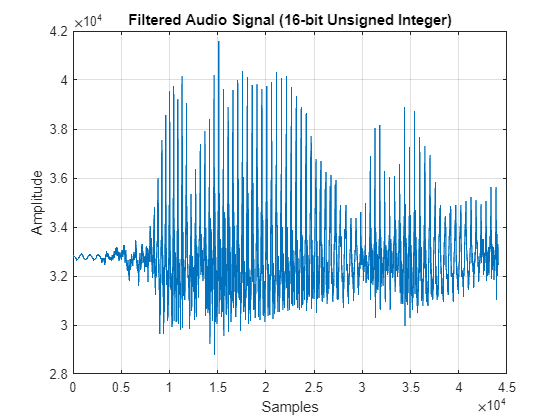


% Retrieve audio data
audioData = getaudiodata(recObj);

% Design a low-pass FIR filter using Hamming window
filterOrder = 50; % Filter order
cutoffFreq = 20000; % Cutoff frequency in Hz
normCutoff = cutoffFreq / (fs / 2); % Normalize cutoff frequency
lowpassFilter = fir1(filterOrder, normCutoff, 'low', hamming(filterOrder + 1));

% Apply the filter to the audio signal
audioDataFiltered = filter(lowpassFilter, 1, audioData);

% Convert filtered audio data to 16-bit unsigned integer with positive values
audioDataFiltered = uint16((audioDataFiltered + 1) * (2^15 - 1)); % Normalize and scale to 16-bit range

% Plot the waveform
figure;
plot(audioDataFiltered);
title('Filtered Audio Signal (16-bit Unsigned Integer)');
xlabel('Samples');
ylabel('Amplitude');
grid on;


% Play the recorded and filtered audio (scaled back to original range for playback)
disp('Playing filtered audio...');

Playing filtered audio...


sound(double(audioDataFiltered) / (2^15 - 1) - 1, fs);

% Write filtered audio data to a coefficient file for Vivado
fid = fopen('audio_coefficients_filtered.coe', 'w');
fprintf(fid, 'memory_initialization_radix=16;');
fprintf(fid, 'memory_initialization_vector=');
for i = 1:length(audioDataFiltered)
    fprintf(fid, '%04X', audioDataFiltered(i));
    if i ~= length(audioDataFiltered)
        fprintf(fid, ',');
    else
        fprintf(fid, ';');
    end
end
fclose(fid);
disp('Coefficient file audio_coefficients_filtered.coe generated successfully.');

Coefficient file audio_coefficients_filtered.coe generated successfully.
